# Sprawozadanie

# z Laboratorium Metod numerycznych

## Ćwiczenie 4:

## Całkowanie numeryczne

Autor: Dominik Gajda, 240661

Maksym Dmytruk, 240353 

Data wykonania ćwiczenia: 16.11.2022

Data sporządzenia i oddania sprawozdania: 21.11.2022

### Część 1. Metoda prostokątów

Napisano funkcje obliczające przybliżoną wartość całki oznaczonej metodą ptostokątów, wariant punktu środkowego.

Funkcja powinna mieć nagłówek

`function S=prostokaty(fun,a,b,n)`

gdzie `fun` oznacza uchwyt do funkcji podcałkowej, `a` i `b` - końce przedziału całkowania, a `n` liczbę podprzedziałów zastosowanych przy wyznaczaniu kwadratury złożonej.

Należało więc zaimplementować obliczanie sumy


$$\int_a^b f(x) d x \approx h \sum_{k=1}^n f\left(a+(k-1)h+\frac{h}{2}\right)$$


gdzie $h=\frac{b-a}{n}$.

Użytecznym "trikiem", pozwalającym skorzystać z faktu, że funkcje testowe są "zwektoryzowane", co pozwala uniknąć użycia pętli, jest zastosowanie polecenia `linspace(a,b,2*n+1)` do wygenerowania siatki punktów, a potem wybranie tylko potrzebnych środków `n` przedziałów,przez odpowiednie wyrażenie indeksowe

Do pierwszego testu, tzw. testu zgodności metody skorzystano z funkcji stałej:

cnst=@(x) 5*ones(size(x)); % Funkcja stała równa 5.
                           % Nietypowa implementacja ma zagwarantować,
                           % że wynik będzie miał wymiar zgodny z argumentem

i obliczono całkę $\int_0^2 cnst(x) d x$=10. Poprawna implementacja którejkolwiek z rozważanych metod MUSI dać dokładny wynik.

Zaimplementowano w/w metodę w formie skryptu, a następnie skopiowano kod do następnej sekcji i przekształcono na funkcję lokalną, stosując polecenie "Convert to local function" z menu kontekstowego.

a=0,b=2

a = 0

b = 2

n=17;
fun=cnst % Przypisanie funkcji stałej do nazwy zmiennej, jaka ma być użyta w ciele funkcji

fun = function_handle with value:
    @(x)5*ones(size(x))


%======================================================================
x=linspace(a, b, 2*n+1); % utworzenie 2n+1 węzłów
y=fun(x(2:2:2*n)); % korzystamy tylko z węzłów o parzystych indeksach
h = (b - a)/n;
S=h*sum(y);
%======================================================================

Po sprawdzeniu kodu (przy użyciu "Run Section") skopiowano kod do nowej sekcji, zaznaczono część między komentarzami z podwójną linią ze znaków równości i wybrano z menu kontekstowego "*Convert to local function*" i nazwano ją `prostokaty`

a=0,b=2

a = 0

b = 2

n=17;
fun=cnst % Przypisanie funkcji stałej do nazwy zmiennej, jaka ma być użyta w ciele funkcji

fun = function_handle with value:
    @(x)5*ones(size(x))


%======================================================================
S = prostokaty(fun,a,b,n)

S = 10

%======================================================================

Wynikiem powyższego kodu powinno być 10 i finalnie taką wartość osiągamy, co świadczy o prawidłowo napisanej funkcji.

Wygenerowano pierwszą funkcję testową przy pomocy generatora `gen3INFcw4` i sporządzono dla niej wykres błędu względnego kwadratury w funkcji liczby podprzedziałów od 2 do 128. Sporządzono następnie wykres wartości bezwzględnej błędu względnego kwadratury w funkcji liczby podprzedziałów w skali logarytmicznej.

[fun1,ab1,tval1,ab,tval]=gen3INFcw4popr(240661,1)

fun1 = function_handle with value:
    @(x)1./(1+sin(x)).^2


ab1 =          0    3.1416


tval1 = 1.3333

ab = '[0,pi]'

tval = '4/3'

Nietypowy sposób przekazania przedziału i dokładnej wartości całki przez generator ma na celu umożliwienie wypisania wzoru informującego o dokładnej wartości całki:


$$\int_{0}^{\pi} \frac{1}{(1+sin(x))^2} d x = \frac{4}{3}$$


Proszę to zrobić dla przydzielonej sobie funkcji (także pozostałych funkcji testowych badanych dalej)

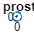

N=2:128;
erwR1=nan(size(N)); % Zarezerwowanie miejsca na zapisanie błędu
for k=1:length(N)
    S=prostokaty(fun1,ab1(1),ab1(2),N(k));
    erwR1(k)=(S-tval1)/tval1;
end
plot(N,erwR1,'o-');
title('Metoda prostokątów')
xlabel('liczba podprzedziałów')
ylabel('błąd względny')

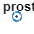

loglog(N,abs(erwR1),'o-');
title('Metoda prostokątów')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

Dla pierwszej funkcji testowej wykres w skali logarytmicznej powinien być zbliżony do linii prostej.

Błąd względny jest odwrotnie proporcjonalny do kwadratu liczby podprzedziałów.

### Część 2. Metoda trapezów.

Zaimplementuj złożoną metodę trapezów z takimi samymi parametrami wejściowymi i nazwą `trapezy`


$$\int_a^b f(x) d x \approx h \sum_{k=1}^n \frac{1}{2}\left(f(a+(k-1)h)+f(a+kh)\right) = h\left(\frac{1}{2}f(a)+\sum_{k=1}^{n-1}f(a+kh)+\frac{1}{2}f(b)\right)$$


a=0,b=2;

a = 0

n=17;
fun=cnst % Przypisanie funkcji stałej do nazwy zmiennej, jaka ma być użyta w ciele funkcji

fun = function_handle with value:
    @(x)5*ones(size(x))


%======================================================================
trapezy(fun, a, b, n);
%======================================================================

a=0,b=2;

a = 0

n=17;
fun=cnst % Przypisanie funkcji stałej do nazwy zmiennej, jaka ma być użyta w ciele funkcji

fun = function_handle with value:
    @(x)5*ones(size(x))


%======================================================================
h=(b-a)/n;
x=linspace(a,b,n+1);
y=fun(x);
S=h*(0.5*(y(1)+y(end))+sum(y(2:end-1)));
%======================================================================
S - 10

ans = 0

Wynikiem różnicy jest zero, zatem funkcja jest napisana prawidłowo.

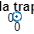

N=2:128;
erwT1=nan(size(N)); % Zarezerwowanie miejsca na zapisanie błędu
for k=1:length(N)
    S=trapezy(fun1,ab1(1),ab1(2),N(k));
    erwT1(k)=(S-tval1)/tval1;
end
plot(N,erwT1,'o-');
title('Metoda trapezów')
xlabel('liczba podprzedziałów')
ylabel('błąd względny')

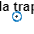

loglog(N,abs(erwT1),'o-');
title('Metoda trapezów')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

Błąd względny jest odwrotnie proporcjonalny do kwadratu liczby podprzedziałów.

### Część 3. Metoda Simpsona.

**Prosty** wzór Simpsona, czyli kwadratura Newtona-Cotes'a o 3 węzłach, a więc bazująca na interpolacji wielomianem stopnia drugiego ma jak wiadomo postać 


$$\int\limits_a^b f(x) d x \approx \frac{b-a}{6}\left(f(a)+4 f\left(\frac{a+b}{2}\right)+f(b)\right)$$


Zwróćmy uwagę, że współczynniki przy wartościach funkcji w węzłach sumują się do wartości 6, która występuje w mianowniku przed nawiasem, więc kwadratura jest **zgodna**, to znaczy jeśli funkcja podcałkowa jest funkcją stałą przyjmującą wartość $C$, to natychmiast sprawdzamy, że wartość całki i wynik kwadratury są równe $C\left(b-a\right)$.

Jeśli mamy zastosować **złożony** wzór Simpsona to znaczy, że mamy podzielić przedział całkowania na $n$ równych podprzedziałów i w każdym z nich zastosować prosty wzór Simpsona. To oznacza, że do obliczenia przybliżonej wartości całki potrzebne będą nie tylko wartości funkcji podcałkowej w końcach przedziału i punktach podziału na podprzedziały, ale także w środkach podprzedziałów!

Podzielono więc przedział $[a,b]$ na $n$ równych podprzedziałów o długości $H=\frac{b-a}{n}$, więc wskazano punkty $xi_k = a + k H,\quad k = 0, 1, 2, \ldots, n$ i obliczono sumę


$$  \int\limits_a^b f(x) d x \approx  \sum_{k=1}^n
  \frac{H}{6}\left(f(\xi_{k-1})+4
f\left(\frac{\xi_{k-1}+\xi_k}{2}\right)+ f(\xi_k)\right) = {}\\
{} = \frac{H}{6}\left( \sum_{k=1}^n f(\xi_{k-1}) + 4 \sum_{k=1}^n
f\left(\frac{\xi_{k-1}+\xi_k}{2}\right) + \sum_{k=1}^n f(\xi_{k})\right) =
{}\\
{}=\frac{H}{6}\left( \sum_{k=0}^{n-1} f(\xi_{k}) + 4 \sum_{k=1}^n
f\left(\frac{\xi_{k-1}+\xi_k}{2}\right) + \sum_{k=1}^n f(\xi_{k})\right) =
{}\\
{}=\frac{H}{6}\left( f(\xi_0) + \sum_{k=1}^{n-1} f(\xi_{k}) + 4
\sum_{k=1}^n
f\left(\frac{\xi_{k-1}+\xi_k}{2}\right) + \sum_{k=1}^{n-1} f(\xi_{k}) +
f(\xi_n)\right) =
{}\\
{}=\frac{H}{6}\left( f(\xi_0) +
f(\xi_n) + 2 \sum_{k=1}^{n-1} f(\xi_{k}) + 4
\sum_{k=1}^n
f\left(\frac{\xi_{k-1}+\xi_k}{2}\right)\right)
$$


Wygodnie jest wprowadzić dwukrotnie gęstszą siatkę punktów


$$x_m = a + m h, \text{  gdzie    } h=\frac{b-a}{2n},\quad m = 0, 1, 2, \ldots, 2 n$$


W tym przypadku mamy $\xi_k = x_{2k}$ oraz

 
$$\frac{\xi_{k-1}+\xi_k}{2} =\frac{a+(k-1)H+ a + kH}{2} = a +(2k-1)h = x_{2k-1}$$


Tak więc przybliżoną wartość całki można zapisać


$$ \int\limits_a^b f(x) d x \approx \frac{H}{6}\left( f(x_0) +
        f(x_{2n}) + 2 \sum\limits_{k=1}^{n-1} f(x_{2k}) + 4
        \sum\limits_{k=1}^n
        f\left(x_{2k-1}\right)\right) = {}\\
        {}=\frac{h}{3}\left( f(a) +
        f(b) + 2 \sum\limits_{k=1}^{n-1} f(x_{2k}) + 4
        \sum\limits_{k=1}^n
        f\left(x_{2k-1}\right)\right)$$


Zaimplementowano tę metodę w postaci funkcji o nagłówku

`function S=simpson(fun,a,b,n)`

a=0,b=2;

a = 0

fun=cnst;
n=17;
%====================================================
simpson(fun, a, b, n);
%====================================================

a=0,b=2;

a = 0

fun=cnst;
n=17;
%====================================================
h=(b-a)/n;
x=linspace(a,b,2*n+1);
y=fun(x);
S=h*(y(1)+y(end)+2*sum(y(3:2:2*n-1))+4*sum(y(2:2:2*n)))/6;
%====================================================
S - 10

ans = 0

Kwadratura zwraca wynik 0, więc jest zgodna z poprzednio napisanymi funkcjami dla zadanych parametrów.

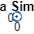

N=2:128;
erwS1=nan(size(N)); % Zarezerwowanie miejsca na zapisanie błędu
for k=1:length(N)
    S=simpson(fun1,ab1(1),ab1(2),N(k));
    erwS1(k)=(S-tval1)/tval1;
end
plot(N,erwS1,'o-');
title('Metoda Simpsona')
xlabel('liczba podprzedziałów')
ylabel('błąd względny')

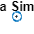

loglog(N,abs(erwS1),'o-');
title('Metoda Simpsona')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

Dla metody Simpsona błąd względny maleje proporcjonalnie do czwartej potęgi liczby podprzedziałów.

### Część 4. Porównanie zaimplementowanych metod.

Narysowano wykresy błędu względnego w funkcji liczby podprzedziałów dla wszystkich zaimplementowanych do tej pory metod.

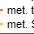

loglog(N,abs(erwR1),'o-',N,abs(erwT1),'s-',N,abs(erwS1),'v-')
legend('met. prostokątów','met. trapezów','met. Simpsona','Location','best')

Przeanalizowano wykres, w celu ustalenia z niego jaki jest rząd poszczególnych metod i określono, która z metod tego samego rzędu ma mniejszą asymptotyczną stałą błędu.

Rząd metody trapezów oraz prostokątów jest ten sam i równy **n**, podczas gdy rząd metody Simpsona wynosi **n+1**, zatem jest dokładniejsza. Metoda prostokątów ma mniejszą asymptotyczną stałą błędu.

### Obserwacje

Charakterystyka błędu metody Simpsona maleje znacznie szybciej w porównaniu do pozostałych dwóch metod: trapezów oraz prostokątów. Metoda prostokątów charakteryzuje się niewiele mniejszym błędem od metody trapezów.

### Uwagi i wnioski

Metoda prostokątów jest w dokładniejsza od metody trapezów. Jej wariant punktu środkowego jest przykładem kwadratury Gaussa, dążącej do zmaksymalizowania stopnia wielomianu zgodnego dla zadanej liczby węzłów.

### Część 5. Porównanie dla innych funkcji testowych.

Generator przykładów gen2INFcw4 oprócz pierwszej funkcji testowej, która jest dość łatwa do całkowania numerycznego, zwraca jeszcze dwie funkcje, które stwarzają pewne trudności. Jedna jest bliska osobliwej, a druga szybko oscyluje. Sporządzono wykresy każdej z nich, a następnie dokonano porównania działania metod prostokątów, trapezów i Simpsona dla tych funkcji. W obydwu przypadkach trzeba rozważyć dużo większą maksymalną liczbę podprzedziałów dla tych porównań (może być potrzebne nawet $2^{40}$ podprzedziałów) - dopiero wtedy charakter wykresu staje się zbliżony dla tego otrzymanego dla pierwszej funkcji.

% Wczytanie funkcji testowych
[fun2,ab2,tval2,ab,tval]=gen3INFcw4popr(240661,2)

fun2 = function_handle with value:
    @(x)5./(x.^2+1/169).^2


ab2 =     -1     1


tval2 =      1.725188783600813e+04


ab = '[-1,1]'

tval = '(373490*atan(13)+28561)/34'

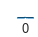

fplot(fun2,ab2)

Druga całka testowa to $\int\limits_{-1}^{1} \frac{5d x}{x^2 + \frac{1}{169}} = \frac{373490 \arctan(13) + 28561}{34} $

[fun3,ab3,tval3,ab,tval]=gen3INFcw4popr(240661,3)

fun3 = function_handle with value:
    @(x)3*x.^2.*sin(x.^3-1)


ab3 =     -5     4


tval3 =   -0.041912442430236


ab = '[-5,4]'

tval = 'cos(126)-cos(63)'

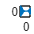

fplot(fun3,ab3)

Trzecia całka testowa to $\int\limits_{-5}^{4} 3x^2\sin(x^3-1) = \cos(126)-\cos(63)$

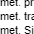

N=2.^(2:23);
erwR2=nan(size(N));
erwT2=nan(size(N));
erwS2=nan(size(N));
for k=1:length(N)
    S=prostokaty(fun2,ab2(1),ab2(2),N(k));
    erwR2(k)=(S-tval2)/tval2;
    S=trapezy(fun2,ab2(1),ab2(2),N(k));
    erwT2(k)=(S-tval2)/tval2;
    S=simpson(fun2,ab2(1),ab2(2),N(k));
    erwS2(k)=(S-tval2)/tval2;
end

loglog(N,abs(erwR2),'o-',N,abs(erwT2),'s-',N,abs(erwS2),'v-')
legend('met. prostokątów','met. trapezów','met. Simpsona','Location','best')
title('Wykres błędu dla drugiej całki testowej')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

N=2.^(2:23);
erwR3=nan(size(N));
erwT3=nan(size(N));
erwS3=nan(size(N));
for k=1:length(N)
    S=prostokaty(fun3,ab3(1),ab3(2),N(k));
    erwR3(k)=(S-tval3)/tval3;
    S=trapezy(fun3,ab3(1),ab3(2),N(k));
    erwT3(k)=(S-tval3)/tval3;
    S=simpson(fun3,ab3(1),ab3(2),N(k));
    erwS3(k)=(S-tval3)/tval3;
end

loglog(N,abs(erwR3),'o-',N,abs(erwT3),'s-',N,abs(erwS3),'v-')
legend('met. prostokątów','met. trapezów','met. Simpsona','Location','best')
title('Wykres błędu dla trzeciej całki testowej')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

### Obserwacje

W przypadku wykresu modułu błędu względnego dla całki bliskiej osobliwej, dla liczby podprzedziałów większej od 1e2 możemy zauważyć, że wartość błędu względnego zaczyna oscylować wokół 1e-15, co może świadczyć o dominacji błędu zaokrągleń względem błędu metody. Wykładnik, zgodnie z którym maleje błąd metod trapezów oraz prostokątów, jest stały powyżej liczby podprzedziałów równej 1e2 i wynosi 2.

W przypadku wykresu modułu błędu względnego dla całki szybko oscylującej, możemy zauważyć, że wartość błędu maleje znacznie wolniej względem pierwszej analizowanej całki. Możemy również zauważyć, że wartość błędu dla liczby podprzedziałów mniejszej od 512 jest większa od jedności dla każdej metody.

### Uwagi i wnioski

Badane metody numeryczne radzą sobie bardzo dobrze z całkami bliskimi osobliwej w porównaniu do łatwo całkowalnych funkcji, pod warunkiem dobrania odpowiednio dużej liczby przedziałów. 

Funkcje oscylujące są całkowalne z dużo większym błędem i w przypadku dobrania odpowiednio dużej liczby węzłów, ich wartość maleje wykładniczo ze stałym wykładnikiem.

### Część 6. Zastosowanie ekstrapolacji Richardsona. Metoda Romberga.

Wyniki całkowania numerycznego można poprawiać stosując ekstrapolację Richardsona. Szczególnie dobrze nadaje się do tego metoda trapezów, ponieważ rozwinięcie jej błędu w szereg Taylora względem długości podprzedziału `h` zawiera tylko parzyste potęgi `h`. Zapoznano się ze składnią wywołania funkcji `ekstrap` i poprawiono wyniki uzyskane w poprzednich sekcjach przy użyciu obliczeń z użyciem metody trapezów. 

Funkcja ekstrap zwraca jako jedną (pierwszą) kolumnę dane wejściowe, poddane ekstrapolacji, więc nie ma potrzeby dołączania ich do porównania - porównać warto natomiast z innymi metodami.

N=2.^(1:13);  % liczba podprzedziałów od 2 do 8192 (potęgi dwójki ze względu na ekstrapolację)
erwR1=nan(size(N));
erwT1=nan(size(N));
erwS1=nan(size(N));
wynT1=nan(size(N));
for k=1:length(N)
    S1r=prostokaty(fun1,ab1(1),ab1(2),N(k));
    S1t=trapezy(fun1,ab1(1),ab1(2),N(k));
    S1s=simpson(fun1,ab1(1),ab1(2),N(k));
    wynT1(k)=S1t;
    erwR1(k)=(S1r-tval1)/tval1;
    erwT1(k)=(S1t-tval1)/tval1;
    erwS1(k)=(S1s-tval1)/tval1;
end
wynEx1=ekstrap(wynT1,2,2:2:16);
erwE1=(wynEx1-tval1)/tval1

erwE1 =    0.472621556370215                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN
   0.140569841524593   0.029885936576052                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN
   0.037540680596462   0.003197626953752   0.001418406312266                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN
   0.009571486347394   0.000248421597705   0.000051807907301   0.000030115869127                 NaN                 NaN                 NaN                 NaN                 NaN
   0.002405334852714   0.000016617687820   0.000001164093828   0.000000360223773   0.000000243534968                 NaN                 NaN                 NaN                 NaN
   0.000602127070606   0.000001057809903   0.000000020484708   0.000000002332183   0.00

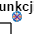

loglog(N,abs(erwR1),'o-',N,abs(erwS1),'+-',N,abs(erwE1),'x-');
legend('Prostokąty', 'Simpson','Ekstrapolacja')
title('Wykres błędu dla funkcji łatwo całkowalnej')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

Spróbuj przeanalizować wyniki, odwołując się także do tablicy z wynikami błędu (w powyższym kodzie `erwE1`) - to powinno pozwolić na wyjaśnienie tego, że niektóre linie wykresu kończą się przedwcześnie.

Tablica `erwE1` jest macierzą trójkatną, 

Spróbuj powtórzyć elsperyment dla pozostałych funkcji testowych.

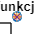

N=2.^(1:13);  % liczba podprzedziałów od 2 do 8192 (potęgi dwójki ze względu na ekstrapolację)
erwR2=nan(size(N));
erwT2=nan(size(N));
erwS2=nan(size(N));
wynT2=nan(size(N));
for k=1:length(N)
    S2r=prostokaty(fun2,ab2(1),ab2(2),N(k));
    S2t=trapezy(fun2,ab2(1),ab2(2),N(k));
    S2s=simpson(fun2,ab2(1),ab2(2),N(k));
    wynT2(k)=S2t;
    erwR2(k)=(S2r-tval2)/tval2;
    erwT2(k)=(S2t-tval2)/tval2;
    erwS2(k)=(S2s-tval2)/tval2;
end
wynEx2=ekstrap(wynT2,2,2:2:16);
erwE2=(wynEx2-tval2)/tval2;
loglog(N,abs(erwR2),'o-',N,abs(erwS2),'+-',N,abs(erwE2),'x-');
legend('Prostokaty','Simpson','Ekstrapolacja')
title('Wykres błędu dla funkcji bliskiej osobliwej')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

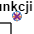

N=2.^(1:13);  % liczba podprzedziałów od 2 do 8192 (potęgi dwójki ze względu na ekstrapolację)
erwR3=nan(size(N));
erwT3=nan(size(N));
erwS3=nan(size(N));
wynT3=nan(size(N));
for k=1:length(N)
    S3r=prostokaty(fun3,ab3(1),ab3(2),N(k));
    S3t=trapezy(fun3,ab3(1),ab3(2),N(k));
    S3s=simpson(fun3,ab3(1),ab3(2),N(k));
    wynT3(k)=S3t;
    erwR3(k)=(S3r-tval3)/tval3;
    erwT3(k)=(S3t-tval3)/tval3;
    erwS3(k)=(S3s-tval3)/tval3;
end
wynEx3=ekstrap(wynT3,2,2:2:16);
erwE3=(wynEx3-tval3)/tval3;
loglog(N,abs(erwR3),'o-',N,abs(erwS3),'+-',N,abs(erwE3),'x-');
legend('Prostokaty','Simpson','Ekstrapolacja')
title('Wykres błędu dla funkcji szybko oscylującej')
xlabel('liczba podprzedziałów')
ylabel('moduł błędu względnego')

### Obserwacje

W przypadku łatwo całkowalnej funkcji, metoda Romberga jest dokładniejsza zarówno od kwadratury Simpsona jak i prostokątów już w trzeciej ekstrapolacji.

W przypadku całki w przybliżeniu osobliwej, ekstrapolacja metodą Romberga przynosi bardzo słabe wyniki, nielepsze od metody prostokątów. Najmniejszy błąd wykazuje w tym przypadku metoda Simpsona.

W przypadku całki szybko oscylującej, już trzecia ekstrapolacja przynosi znacznie dokładniejsze wyniki od metody Simpsona, a nawet prowadzi do spadku błędu do 1e-12, jednak dopiero w przypadku, gdy liczba przedziałów przekroczy 1e3.

### Uwagi i wnioski

Metoda Romberga jest znacznie dokładniejsza podczas całkowania łatwo całkowalnych funkcji. W przypadku funkcji szybko oscylujących, należy zadbać o dużą liczbę podprzedziałów, natomiast w przypadku funkcji bliskich osobliwym, nie należy jej stosować. 

Metoda Simpsona może okazać się wystarczająca do obliczania większości całek pod warunkiem dobrania wystarczająco dużej liczby węzłów odzwierciedlających szybkość zmieniania się funkcji.

function S = prostokaty(fun, a, b, n)
x=linspace(a, b, 2*n+1);
y=fun(x(2:2:2*n));
h = (b - a)/n;
S=h*sum(y);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function S = trapezy(fun, a, b, n)
h=(b-a)/n;
x=linspace(a,b,n+1);
y=fun(x);
S=h*(0.5*(y(1)+y(end))+sum(y(2:end-1)));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function S = simpson(fun, a, b, n)
h=(b-a)/n;
x=linspace(a,b,2*n+1);
y=fun(x);
S=h*(y(1)+y(end)+2*sum(y(3:2:2*n-1))+4*sum(y(2:2:2*n)))/6;
end